# 6.2 分布同士の距離を測る

### 図 6.2.1 コルモゴロフ・スミルノフ統計量

% シード値を固定
rng('default');

% サンプルサイズを設定。
sample_size = 1000;

% 一つ目と二つ目の分布ペアを生成
mean1 = 0; std1 = 1;
mean2 = 0.1; std2 = 1;
dist1 = mean1 + std1 .* randn(sample_size, 1);
dist2 = mean2 + std2 .* randn(sample_size, 1);

% Kolmogorov-Smirnov 統計量を計算 
[~, ~, ks_stat, p_value] = kstest2(dist1, dist2);

Error using kstest2
Too many output arguments.


% 累積分布関数 (CDF) を計算。
dist1_sorted = sort(dist1);  % dist1をソート
dist2_sorted = sort(dist2);  % dist2をソート
cdf1 = cumsum(ones(sample_size, 1)) / sample_size;  % dist1のCDFを計算
cdf2 = cumsum(ones(sample_size, 1)) / sample_size;  % dist2のCDFを計算

% 図の準備
figure('units','normalized','outerposition',[0, 0, 0.8,0.8]);

% 共通のビンを設定
bin_edges = linspace(min([dist1; dist2]), max([dist1; dist2]), 51);

% ヒストグラムをプロット
subplot(2, 1, 1);
histogram(dist1, 'BinEdges', bin_edges, 'FaceAlpha',0.5, 'DisplayName', '分布１');
hold on
histogram(dist2, 'BinEdges', bin_edges, 'FaceAlpha',0.5, 'DisplayName', '分布２');
legend();  % 凡例を表示
ylabel('頻度');  % y軸ラベルを設定

% CDFをプロット
subplot(2, 1, 2);
plot(dist1_sorted, cdf1, 'DisplayName', '分布１');
hold on
plot(dist2_sorted, cdf2, 'DisplayName', '分布２');

% CDFの差の最大値を見つける
% まずdist1_sortedとdist2_sortedをマージしてソート
merged_sorted_dists = sort([dist1_sorted; dist2_sorted]);

% 全体の中でそれぞれの分布のそれぞれの値がどこにあるかを計算
idx1 = cumsum(histc(dist1_sorted, merged_sorted_dists) > 0) / sample_size;
idx2 = cumsum(histc(dist2_sorted, merged_sorted_dists) > 0) / sample_size;

% y方向の差の最大値とその位置を求める
[max_diff_y, max_diff_y_idx] = max(abs(idx1 - idx2));

% 最大差に対応する場所に線を引く
x_max_diff = merged_sorted_dists(max_diff_y_idx);
y1_max_diff = idx1(max_diff_y_idx);
y2_max_diff = idx2(max_diff_y_idx);

% 縦線をプロットして最大差を表示
plot([x_max_diff, x_max_diff], [y1_max_diff, y2_max_diff],...
    'Color', 'gray', 'LineStyle', '-', 'LineWidth', 2)
text(max_diff_y_idx-50, 0.5 ,['最大差: ', num2str(max_diff_y)]);

% CDFプロットの設定
title(['コルモゴロフ・スミルノフ統計量: ', num2str(ks_stat), ', p値: ', num2str(p_value)]);
legend();  % 凡例を表示
ylabel('累積分布');  % y軸ラベルを設定

% グラフを表示します。
drawnow;

% 画像を保存
% print('../figures/6_2_1_Kolmogorov_Smirnov', '-dpng', '-r300');


### 図 6.2.2 全変動距離を求める

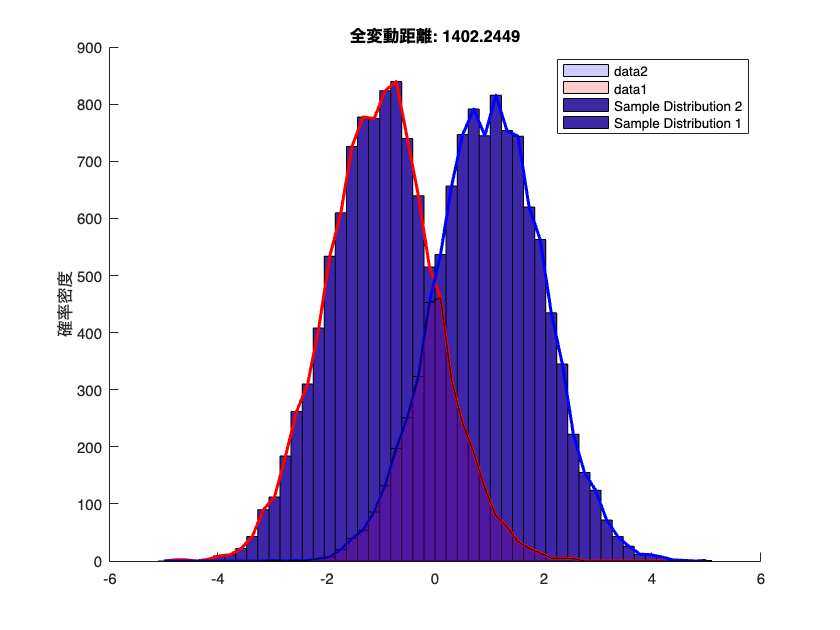

% シード値を固定
rng('default');

% 正規分布のパラメータ（平均と標準偏差）
mu1 = -1; sigma1 = 1;
mu2 = 1; sigma2 = 1;

% サンプルデータの生成
num_samples = 10000;
samples1 = normrnd(mu1, sigma1, [num_samples, 1]);
samples2 = normrnd(mu2, sigma2, [num_samples, 1]);

% ビンの設定
bins = linspace(-5, 5, 50);

% ヒストグラムを計算
[hist1, bin_centers] = hist(samples1, bins, 'Normalization', 'probability');
hist2 = hist(samples2, bins, 'Normalization', 'probability');

% 全変動距離（TVD）を計算
tvd_sample = 0.5 * sum(abs(hist1 - hist2)) * (bin_centers(2) - bin_centers(1));

% サンプルデータに対する全変動距離と面積を表示
figure;  % 新しい描画ウィンドウを開く
hold on;  % 現在の描画を保持
hist(samples1, bins, 'FaceColor', 'gray', 'FaceAlpha', 0.3, 'Normalization', 'probability');
hist(samples2, bins, 'FaceColor', 'blue', 'FaceAlpha', 0.3, 'Normalization', 'probability');
plot(bin_centers, hist1, 'r-', 'LineWidth', 2);
plot(bin_centers, hist2, 'b-', 'LineWidth', 2);
legend('Sample Distribution 1', 'Sample Distribution 2');
title(['全変動距離: ', num2str(tvd_sample, '%.4f')]);
ylabel('確率密度');

% 強制的に範囲を設定して間を塗りつぶすための手続き
area(bin_centers, min([hist1; hist2],[],1), 'FaceColor', 'red', 'FaceAlpha', 0.2);
area(bin_centers, min([hist1; hist2],[],1), 'FaceColor', 'blue', 'FaceAlpha', 0.2);
hold off;  % 現在の描画の保持を解除


% レイアウトの設定
% set(gca, 'LooseInset', get(gca, 'TightInset'));  % 図の周囲の余白を削除

% 図の保存
% print('../figures/6_2_2_total_variation','-dpng','-r300');

### 図 6.2.3 ワッサースタイン計量の計算のイメージ

% シード値を固定
rng('default'); 

% 正規分布のパラメータ（平均と標準偏差）
mu1 = 0; sigma1 = 1;
mu2 = 2; sigma2 = 1;

% サンプルデータの生成
num_samples = 50;
samples1 = normrnd(mu1, sigma1, [num_samples,1]);
samples2 = normrnd(mu2, sigma2, [num_samples,1]);

% ソート
samples1 = sort(samples1);
samples2 = sort(samples2);

% 可視化
figure('Position', [10 10 800 400]);  % 図の準備
scatter(samples1, ones(num_samples,1), 'MarkerEdgeColor','red', 'DisplayName','分布１'); hold on; % マーカーを設定
scatter(samples2, zeros(num_samples,1), 'MarkerEdgeColor','blue', 'DisplayName','分布２'); hold on; % マーカーを設定

% 最短距離を繋ぐ線を描画
for idx = 1:num_samples
    line([samples1(idx), samples2(idx)], [1, 0], 'Color','k', 'LineWidth',1);
end

yticks([0, 1]); % y軸の目盛りを設定
yticklabels({'分布２', '分布１'}); % Y軸のラベルを設定
legend; % 凡例の表示

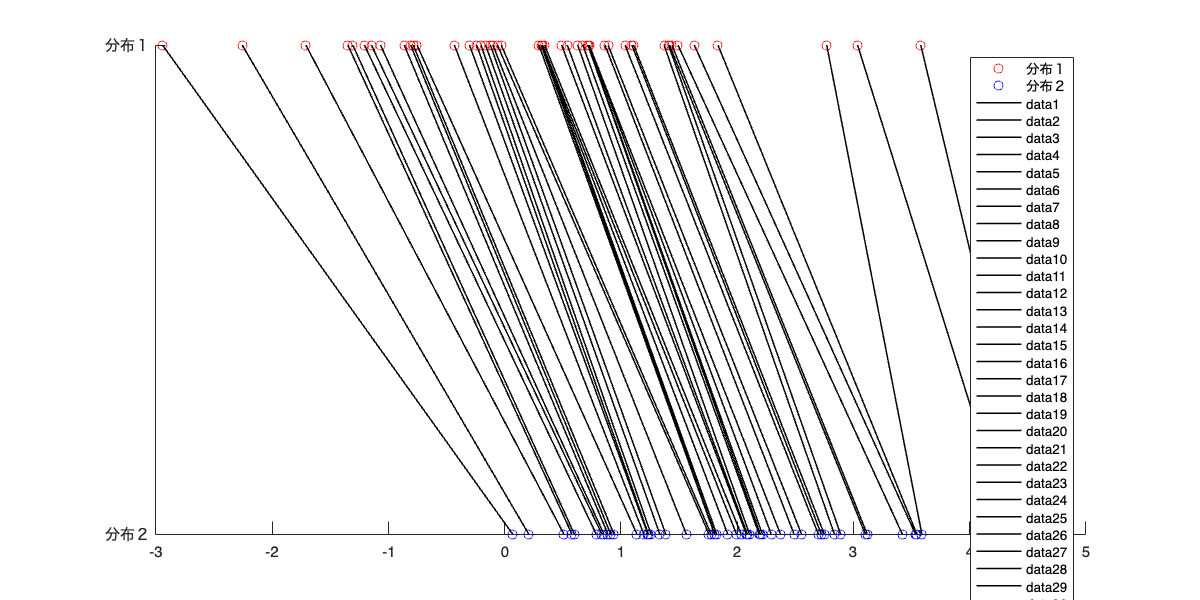

hold off;


% 図の保存
% print('../figures/6_2_3_wasserstein_distance','-dpng','-r300');  


### 図 6.2.4 カルバック・ライブラー情報量とイェンセン・シャノン情報量

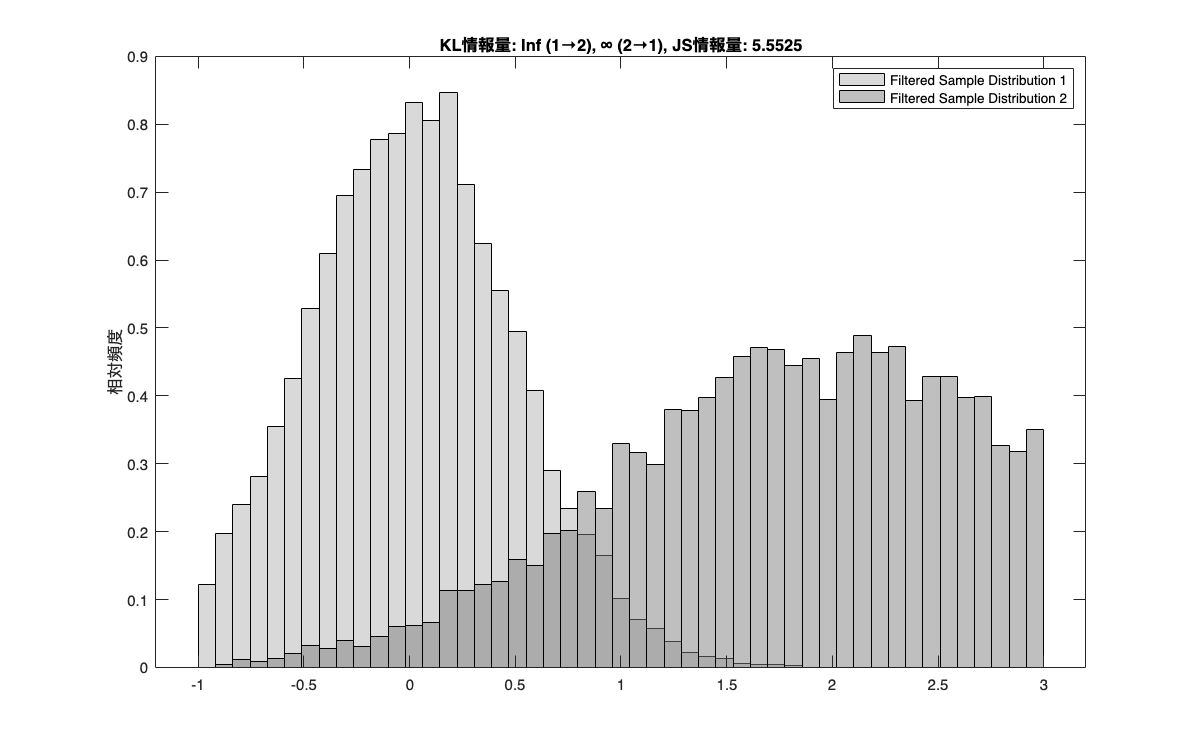

% シード値を固定
rng('default');

% KL情報量を計算する関数
kl_divergence = @(p, q) sum(p .* log(p ./ q + (p == 0)));

% 正規分布のパラメータ (平均と標準偏差)
mu1 = 0; sigma1 = 0.5;
mu2 = 2; sigma2 = 1;

% サンプルデータの生成
num_samples = 10000;
samples1 = mu1 + sigma1 .* randn(num_samples, 1);
samples2 = mu2 + sigma2 .* randn(num_samples, 1);

% サンプルを[-1, 3]の範囲に絞り込む
filtered_samples1 = samples1(samples1 >= -1 & samples1 <= 3);
filtered_samples2 = samples2(samples2 >= -1 & samples2 <= 3);

% 非ゼロのビンを確保するために、限られた範囲でヒストグラムを生成
limited_bins = linspace(-1, 3, 50);
hist1 = histcounts(filtered_samples1, limited_bins, 'Normalization', 'pdf');
hist2 = histcounts(filtered_samples2, limited_bins, 'Normalization', 'pdf');

% ヒストグラムを正規化
bin_width = limited_bins(2) - limited_bins(1);
hist1 = hist1 / sum(hist1 .* bin_width);
hist2 = hist2 / sum(hist2 .* bin_width);

% KLダイバージェンスを再計算
kl_1_to_2 = kl_divergence(hist1, hist2);
kl_2_to_1 = kl_divergence(hist2, hist1);

% JSダイバージェンスを再計算
js_divergence = 0.5 * (kl_divergence(hist1, 0.5 * (hist1 + hist2)) + ...
                       kl_divergence(hist2, 0.5 * (hist1 + hist2)));

% ヒストグラムを再描画し、ダイバージェンスを表示
figure('Position', [10 10 800 500]);
hist1_handle = histogram(filtered_samples1, 'BinEdges', limited_bins, 'Normalization', 'pdf', 'FaceColor', [0.7 0.7 0.7], 'FaceAlpha', 0.5);
hold on;
hist2_handle = histogram(filtered_samples2, 'BinEdges', limited_bins, 'Normalization', 'pdf', 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.5);
hold off;
legend('Filtered Sample Distribution 1', 'Filtered Sample Distribution 2');

% タイトルを設定
title(sprintf('KL情報量: %.4f (1→2), ∞ (2→1), JS情報量: %.4f', kl_1_to_2, js_divergence));
ylabel('相対頻度');  % y軸ラベルを設定


% 図の保存
% print('../figures/6_2_4_kl_js_divergence', '-dpng', '-r300');  % DPIを300に設定して保存


### 図 6.2.5 様々な分布間距離指標

% 各距離を計算する関数を定義
ksstatistic = @(x, y) max(abs(cdf(empiricalCdf(x), y) - cdf(empiricalCdf(y), y)));
kl_divergence = @(p, q) sum(p.*log(p./q));
total_variation_distance = @(p, q) 0.5*sum(abs(p - q));
js_divergence = @(p, q) 0.5*kl_divergence(p, 0.5*(p + q)) + 0.5*kl_divergence(q, 0.5*(p + q));
wasserstein_distance = @(u,v,p_u,p_v) munkres(abs(reshape(v, length(v), 1) - reshape(u, 1, length(u))));
compute_metrics = @(dist_a, dist_b, bin_edges) [...
    ksstatistic(dist_a, dist_b),...
    total_variation_distance(histcounts(dist_a, bin_edges, 'Normalization', 'probability'), histcounts(dist_b, bin_edges, 'Normalization', 'probability')),...
    wasserstein_distance(bin_edges(1:(end-1)), bin_edges(1:(end-1)), histcounts(dist_a, bin_edges, 'Normalization', 'probability'), histcounts(dist_b, bin_edges, 'Normalization', 'probability')),...
    js_divergence(histcounts(dist_a, bin_edges, 'Normalization', 'probability'), histcounts(dist_b, bin_edges, 'Normalization', 'probability'))...
];

% サンプルサイズとパラメータを設定
sample_size = 1000;
mean1 = 0; std1 = 1;
mean2 = 1; std2 = 1;
mean3 = -1; std3 = 0.5;
mean4 = 1; std4 = 1.5;
mean5 = -2; std5 = 1;
mean6 = 2; std6 = 1;
mean7 = 0; std7 = 1.5;

% データを生成
rng('default');
dist1_1 = normrnd(mean1, std1, sample_size, 1);
dist1_2 = normrnd(mean2, std2, sample_size, 1);
dist2_1 = normrnd(mean3, std3, sample_size, 1);
dist2_2 = normrnd(mean4, std4, sample_size, 1);
dist3_1 = [normrnd(mean5, std5, sample_size/2, 1);
           normrnd(mean6, std6, sample_size/2, 1)];
dist3_2 = normrnd(mean7, std7, sample_size, 1);

% 全体で使用する色を設定
common_colors = ['b'; 'r'];

% ビンのエッジを計算
all_data = [dist1_1; dist1_2; dist2_1; dist2_2; dist3_1; dist3_2];
min_val = min(all_data);
max_val = max(all_data);
bin_edges = linspace(min_val, max_val, 21);

% 各距離指標を計算
metrics = ["KS-statistic"; "TV-distance"; "Wasserstein"; "JS-divergence"];
distances1 = compute_metrics(dist1_1, dist1_2, bin_edges);

Unrecognized function or variable 'empiricalCdf'.

Error in chapter6_2>@(x,y)max(abs(cdf(empiricalCdf(x),y)-cdf(empiricalCdf(y),y))) (line 204)
ksstatistic = @(x, y) max(abs(cdf(empiricalCdf(x), y) - cdf(empiricalCdf(y), y)));

Error in 

distances2 = compute_metrics(dist2_1, dist2_2, bin_edges);
distances3 = compute_metrics(dist3_1, dist3_2, bin_edges);

% 棒グラフのY軸のスケールを調整
max_distance = 2.5;

% ヒストグラムを描画
figure(1);
subplot(1, 3, 1);
histogram(dist1_1, 'BinEdges', bin_edges, 'Normalization', 'probability', 'FaceAlpha', 0.5, 'FaceColor', common_colors(1));
hold on;
histogram(dist1_2, 'BinEdges', bin_edges, 'Normalization', 'probability', 'FaceAlpha', 0.5, 'FaceColor', common_colors(2));
title('分布ペア1');
hold off;

subplot(1, 3, 2);
histogram(dist2_1, 'BinEdges', bin_edges, 'Normalization', 'probability', 'FaceAlpha', 0.5, 'FaceColor', common_colors(1));
hold on;
histogram(dist2_2, 'BinEdges', bin_edges, 'Normalization', 'probability', 'FaceAlpha', 0.5, 'FaceColor', common_colors(2));
title('分布ペア2');
hold off;

subplot(1, 3, 3);
histogram(dist3_1, 'BinEdges', bin_edges, 'Normalization', 'probability', 'FaceAlpha', 0.5, 'FaceColor', common_colors(1));
hold on;
histogram(dist3_2, 'BinEdges', bin_edges, 'Normalization', 'probability', 'FaceAlpha', 0.5, 'FaceColor', common_colors(2));
title('分布ペア3');
hold off;

% saveas(gcf, 'dist_pairs.png');
% close gcf;

% 棒グラフを描画
figure(2);
bar([distances1 distances2 distances3]');
legend('分布ペア1', '分布ペア2', '分布ペア2');
title('各指標における分布ペアの距離');
set(gca, 'XTickLabel',{'KS-statistic', 'TV-distance', 'Wasserstein', 'JS-divergence'});
ylim([0, max_distance]);
% saveas(gcf, 'dist_metrics.png');
% close gcf;
